# Arch Forecasting

After using information criteria to select the best model for the volatility of the returns of the S&P 500, we will now turn to use this model for forecasting. Since we always like to keep models that are as parsimonious as possible, we will consider the TARCH(1,1,1) model that was selected via the BIC in this forecasting exercises. 

## **Exercise** 68

Exercise 68 asks us to estimate our TARCH(1,1,1) in the first half of the sample and construct forecasts in the remaining period. 

Let's begin by uploading the S&P 500 data that we saved from the previous class. 

clear all
clc
% Downloading the SP500 data: 
load sp_data

Moreover, because we are not interested in seeing all the iterations when estimating our models, let's select this option.

options.Display = 'none';

Ok. Now that we are done with the basics, we can split the sample between the parts that we will use for estimation and forecasting.

% Setting the T's:
T = length(r_sp);
T_half = floor(length(r_sp)/2);
% Setting the vectors of returns:
r_is = r_sp(1:T_half);
r_oos = r_sp(T_half+1:end);

### Estimating the Model

After splitting the sample, we can estimate the model using only the observations from the first half:

[parameters,ll,ht]=tarch(r_is,1,1,1,[],1,[], options);

### Forecasting

The idea is that we now use the parameters estimated by this TARCH(1,1,1) to forecast the volatility for the second half of the sample. Remember that for ARMA models we had a function that did this for us. This time, we will perform the forecasts by "brute force". That is, we will construct the code that generates the forecasts. 

We will build a vector of forecasts `sqrt_ht_forecast` that will have the value of our forecasts for the entire sample `T`. This will include both in sample forecasts (from `1` to `T_half`) and out of sample forecasts (from `T_half` to `end`). So let's do it!

% Creating the forecasts vector:
sqrt_ht_forecast = zeros(T,1);
sqrt_ht_forecast(1:T_half) = sqrt(ht);

% Getting the parameters we have estimated:
omega = parameters(1);
alpha = parameters(2);
gamma = parameters(3);
beta = parameters(4);

% Forecasting:
for t=T_half+1:T
    sqrt_ht_forecast(t) = omega + alpha * abs(r_sp(t-1)) ...
        + gamma * abs(r_sp(t-1)) * (r_sp(t-1)<0) ...
        + beta * sqrt_ht_forecast(t-1);
end
ht_forecast = sqrt_ht_forecast.^2;

## **Exercise** 69

The next exercise asks us to evaluate the accuracy of these forecasts. We can test absolute accuracy of a model's forecast by using the MZ regression (remember the theory class from earlier today). Here, we will consider the non-expanded version of the MZ framework; that is, without other regressors. In this standard MZ framework, we regresse the variance forecast error on the forecast and a constant.

So let's begin with the MZ Regression:

% Getting the OOS variance forecasts:
ht_oos = ht_forecast(T_half+1:end);

% MZ Regression
y = r_oos.^2 - ht_oos;
x = ht_oos;
[b,~,~,~,vcv_white] = ols(y,x,1);

Now lets check if the coefficients of the MZ regression are zero. First, taking a look at individual t-stats:

t_stats = b./sqrt(diag(vcv_white))

t_stats =      -0.48802
     -0.29388


Then taking a look at the joint hypothesis that they are jointly equal to zero:

% Calculating the wald statistic:
wald = b' * inv(vcv_white) * b;
% Checking the p-val of the test:
pval = 1 - chi2cdf(wald,2)

pval =      0.046122


Although the model seems to be forecasting well with both coefficients very close to zero, we are (marginally) able to reject the null that the two coefficients are jointly zero at 5% significance.

## **Exercise** 70

This exercise asks us to perform the same analysis we did for our TARCH(1,1,1) to a  2-year backward moving average variance model. That is, we will use the mean of $r^2$ of the previous two years to forecast variance.

First, let's generate the forecasts from this simple model (using 252 business day as a year):

% Creting the forecasts vector:
ma_ht = zeros(T-T_half,1);
% Forecasting:
for t=(T_half+1):T
    ma_ht(t-T_half) = mean(r_sp(t-(1:(2*252))).^2);
end

Now let's evaluate these forecasts with the MZ Regression:

% MZ Regression
y = r_oos.^2 - ma_ht;
x = ma_ht;
[b,~,~,~,vcv_white] = ols(y,x,1);

Now lets check if the coefficients of the MZ regression are zero. First, taking a look at individual t-stats:

t_stats = b./sqrt(diag(vcv_white))

t_stats =        5.4375
       -5.936


Then taking a look at the joint hypothesis that they are jointly equal to zero:

% Calculating the wald statistic:
wald = b' * inv(vcv_white) * b;
% Checking the p-val of the test:
pval = 1 - chi2cdf(wald,2)

pval =    1.4867e-09


And this is how a bad model looks like! Now we see that even the individual t-stats reject the individual nulls that their coefficients are equal to zero. As expected, we can strongly reject the null that both coefficients are jointly equal to zero.

## **Exercise** 71

To conclude, let's compare the two models we have estimated in here. Relative performance is accessed using Diebold-Mariano tests.  Let's take a look at Kevin's slides just to understand the code:

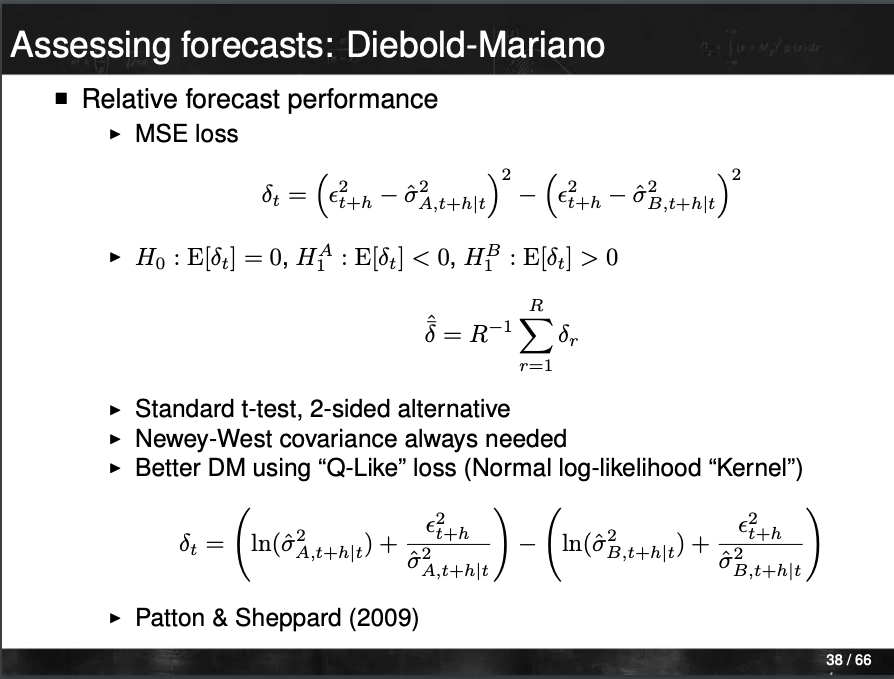

We will follow the "better" DM version using the "Q-Like" loss. The idea is that we calculate this $\delta_t$ series and check whether the models are the same (from a forecasting perspective) by regressing this $\delta_t$ series on a constant using Newey-West errors.  We then test the null that this constant is equal to zero. If we cannot reject the null, then the two models have similar forecasting performance. If the constant is significantly greater than zero, then model B has better forecasting performance. On the other hand, if the constant is significantly lower than zero, then model A has better forecasting performance than model B.

% Calculating the delta:
la = log(ht_oos) + r_oos.^2./ht_oos;
lb = log(ma_ht) + r_oos.^2./ma_ht;
delta = la-lb;
% Estimating the regression:
[dm,tstat] = olsnw(delta,[],1)

dm =       -0.4539


tstat =       -4.9721


The tstat indicates that the two models are significantly different from a forecasting perspective. Moreover, the negative value shows that model A is better than model B; that is, that our selected TARCH(1,1,1) model outperforms the moving average model with regards to its out of sample forecasting performance. This is in line with what we found in the MZ regression framework.